Jeremy Primus

MECH532

HW10

1)

% initialization
clear all
global epsilon_a sigma_a E
epsilon_a = [0.02 0.015 0.01 0.006 0.0035 0.002];   % strain amplitude
sigma_a = [650 625 555 480 395 330];                % stress amplitude (MPa)
n_f = [200 350 1100 4600 26000 560000];             % cycles to failure
E = 216e3;                                          % elastic modulus  (Mpa)

a.

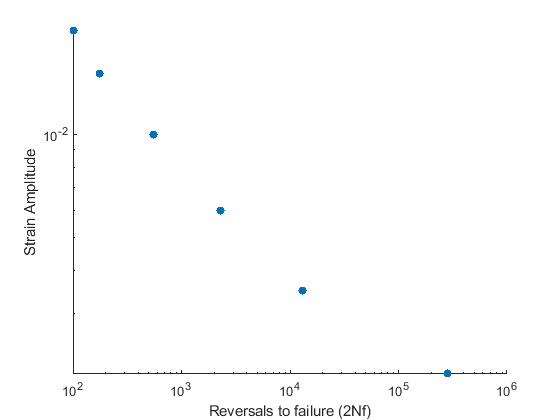

% exploratory data analysis
scatter(n_f./2, epsilon_a, 'filled')
set(gca, 'xscale', 'log')
set(gca, 'yscale', 'log')
ylabel('Strain Amplitude')
xlabel('Reversals to failure (2Nf)')

b.

so = [1,1];
fit_params = fminsearch(@lsfit1b, so);
n = fit_params(1)

n = 0.1999

K = fit_params(2)

K = 1.4773e+03

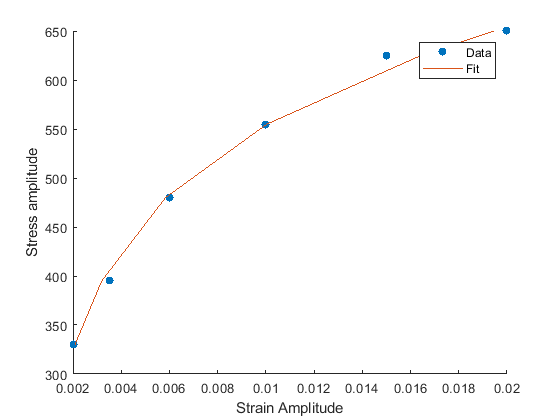

figure()
scatter(epsilon_a, sigma_a, 'filled')
hold on
plot(sigma_a/E + (sigma_a/K).^(1/n), sigma_a)
xlabel('Strain Amplitude')
ylabel('Stress amplitude')
legend('Data', 'Fit')

c.

sigma_cyclic = (240:-1:0);
epsilon_cyclic(1) = 0.003;
for i = 2:length(sigma_cyclic)
    epsilon_cyclic(i) = epsilon_cyclic(i-1) - (1/E + 2*(sigma_cyclic(i)/(2*K)).^(1/n));
end
figure()
plot(epsilon_cyclic, sigma_cyclic)
hold on
sigma_cyclic2 = (0:-1:-240);
epsilon_cyclic2(1) = epsilon_cyclic(end);
for i = 2:length(sigma_cyclic2)
     epsilon_cyclic2(i) = epsilon_cyclic2(i-1) - (1/E + 2*(sigma_cyclic2(i)/(2*K)).^(1/n));
end
plot(epsilon_cyclic2, sigma_cyclic2)

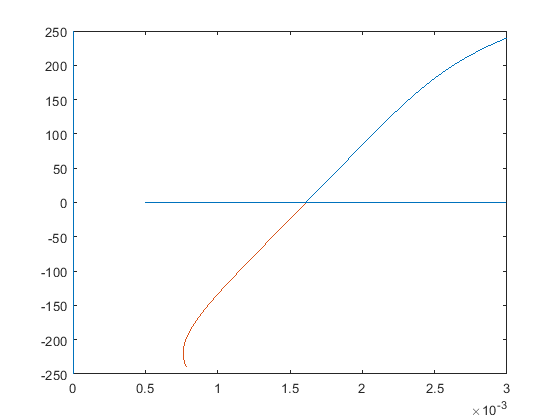

hold on
xL = xlim;
yL = ylim;
line([0 0], yL);  %x-axis
line(xL, [0 0]);  %y-axis
hold off

Problem 2.

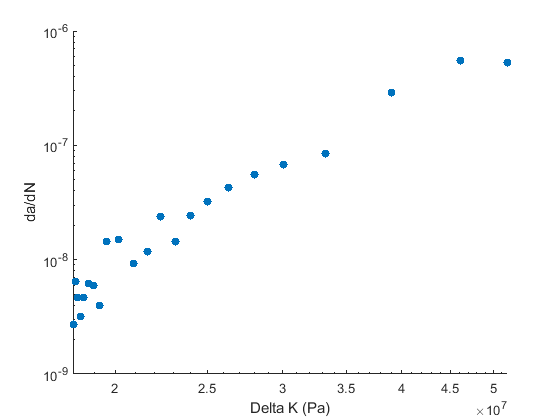

% Initialization
clear all
global da_dN delta_K_I
N = [0 37100 68300 111200 173500 238000 286400 371000 446200 501200 560900 691800 751200 801600 863400 908800 942900 978000 1006700 1028900 1059700 1069400 1073200 1074900];  % cycles
a = [22.0 22.1 22.3 22.5 22.7 23.0 23.3 23.8 24.1 24.9 25.8 27.0 27.7 28.9 29.8 30.9 32.0 33.5 35.1 36.6 39.2 42.0 44.1 45.0]*1e-3;                                                 % crack length
Pmax = 6.14e3;
Pmin = 0.89e3;
w = 64.8e-3;
b = 8.2e-3;

da_dN = diff(a)./diff(N);   % secant method
deltaP = Pmax-Pmin;
for i = 1:(length(a)-1)
    a_avg(i) = (a(i)+a(i+1))/2;
end
delta_K_I = (deltaP*sqrt(a_avg)/(b*w)).*(30.96 - 195.8*(a_avg/w) + 730.6*(a_avg/w).^2 - 1186.3*(a_avg/w).^3 + 754.6*(a_avg/w).^4);

%loglog(delta_K_I, da_dN)
scatter(delta_K_I, da_dN, 'filled')
set(gca, 'xscale', 'log')
set(gca, 'yscale', 'log')
ylabel('da/dN')
xlabel('Delta K (Pa)')

% fit region II to Paris Power Law
% from the above plot, it looks like delta_K_I(11) - delta_K_I(20) would be a good bet for region II - see lsfit function definition
figure()
scatter(delta_K_I(11:20)/1e6, da_dN(11:20), 'filled')
set(gca, 'xscale', 'log')
set(gca, 'yscale', 'log')
ylabel('da/dN')
xlabel('Delta K (MPa)')
hl = lsline;
so = [1,1000];
options = optimset('MaxFunEvals',1000);
fit_params = fminsearch(@lsfit2,so, options);

 
Exiting: Maximum number of iterations has been exceeded
         - increase MaxIter option.
         Current function value: 1.128514 



m = fit_params(1)

m = -0.4191

A = fit_params(2)

A = 3.8724e+10

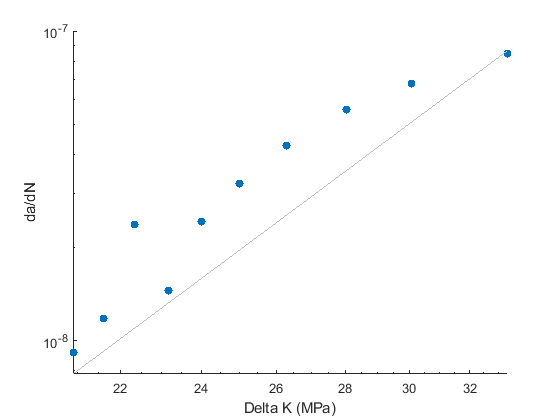

hold on

% plot(delta_K_I(11:20), fit_params(2)*delta_K_I(11:20).^fit_params(1)) 

Had some question on the units in Paris power law... didn't have time to figure it out

Problem 3.

% Initialization
clear all
w = 20e-2;
b = 0.3e-2;
ao = 1e-2;
sigma_min = 0;
sigma_max = 80e3/(b*w); % b*w = cross sectional area over which load is distributed
f = 25;
syms ac
a_c = vpasolve((1.12 - 0.231*(ac/w) + 10.55*(ac/w)^2 - 21.72*(ac/w)^3 + 30.95*(ac/w)^4)*sigma_max*sqrt(pi*ac) == 60e6, ac)

$$a\_c = -0.035006086253913735962239603294163+0.042177508105679483294063014391395\,\mathrm{i}$$

not sure why this value comes out negative...

fun = @(a) 1./(a.^2.25.*(1.12 - 0.231*(a/w) + 10.55*(a/w).^2 - 21.72*(a/w).^3 + 30.95*(a/w).^4));
N = 1/(1.36e-10*(1e-6*sigma_max*sqrt(pi))^2.25)*integral(fun, ao, 0.035)

N = 5.7468e+06

t = (N/25)/360;     % time in hours
d = t*5             % escape distance in km

d = 3.1927e+03

Seems quite long.  Didn't have time to verify.

Problem 4.

S_yt = 481e6;
sigma_f = 1326e6;
b = -0.103;
c = -0.581;


sigma_mean = 0.25*S_yt

sigma_mean = 120250000

% function definitions
% least squares fit

function s = lsfit1b(so)
global epsilon_a E sigma_a 
    s = sum((log10(epsilon_a - sigma_a/E) - (1/so(1))*log10(sigma_a/so(2))).^2);
end
function s = lsfit2(so)
global da_dN delta_K_I
    s = sum((log10(da_dN(11:20)) - so(1)*(log10(so(2)) + log10(delta_K_I(11:20)))).^2);
end